# Sistemas Realimentados - 2023/2

## Nome: Luiza Batista Laquini

## Data limite para entrega: 4/10, 6h da manhã.

## Trabalho 3 - Projeto de controladores PID via método do lugar das raízes.

I=21; % Seu valor de I
[G1,G2,G3, iae_G1, iae_G3, ts_G2]=ini_t3(I);
datetime('now')

ans = datetime
   04-Oct-2023 00:04:58


Abaixo, chamamos 'tf' transformando 's' em uma função de transferência que vai facilitar a montagem dos controladores posteriormente.

s=tf('s'); 

**Atividade 1: Projeto de um controlador PI para sistema de primeira ordem + tempo morto (G1(s)). **

Projetar um controlador PI via método do lugar das raízes usando a FT G1. O  controlador resultante C1 deve resultar em um valor de $IAE\leq iae_{G1}$ e erro nulo para entrada degrau.

Mostrar o controlador e o LR utilizado, explicar as escolhas da localização do zero do controlador para atender a especificação e a obtenção de Kp e Ki do LR.

G1

G1 =
 
                 10
  exp(-9*s) * --------
              36 s + 1
 
Continuous-time transfer function.
Model Properties


iae_G1

iae_G1 = 20.1513

Em primeiro lugar, como nossa G1 possui tempo morto, é necessário fazer a aproximação por Padé:

G1p=pade(G1)

G1p =
 
      -10 s + 2.222
  ---------------------
  36 s^2 + 9 s + 0.2222
 
Continuous-time transfer function.
Model Properties


polos_G1p=pole(G1p)

polos_G1p =    -0.2222
   -0.0278


Agora, com a FT aproximada - com dois polos localizados em -0.2222 e -0.0278 - podemos projetar o controlador PI via LR. 

O controlador PI é dado por:


$$\textrm{Gc}\left(s\right)=\textrm{Kp}+\frac{\textrm{Ki}}{s}$$


ou 


$$\textrm{Gc}\left(s\right)=\textrm{Kp}+\frac{\left(s+\frac{\textrm{Ki}}{\textrm{Kp}}\right)}{s}$$


Ele adiciona um polo na origem (aumentando assim o tipo do sistema e contribuindo para atender o erro em regime) e um zero. 

O projeto do PI via LR envolve escolher a localização do zero e o ganho Kp. Depois disto, calcula-se o ganho KI.

Importante: Sabemos que o zero do PI próximo à origem tende a deixar a resposta lenta e, analogamente, o zero do PI muito longe da origem tende a deixar a resposta menos amortecida (maior sobreelevação), dessa forma, o ganho Kp deve ser aumentado de modo a conseguir respostas mais rápidas.

Para fazer isso, vamos chamar a função 'rltool' do matlab que nos permite modificar o LR adicionando o polo na origem e o zero necessários e, então, alterar o valor de Kp.

%rltool(G1p)

Ao chamar 'rltool', o LR obtido para a G1 após aproximação de Padé é o seguinte:

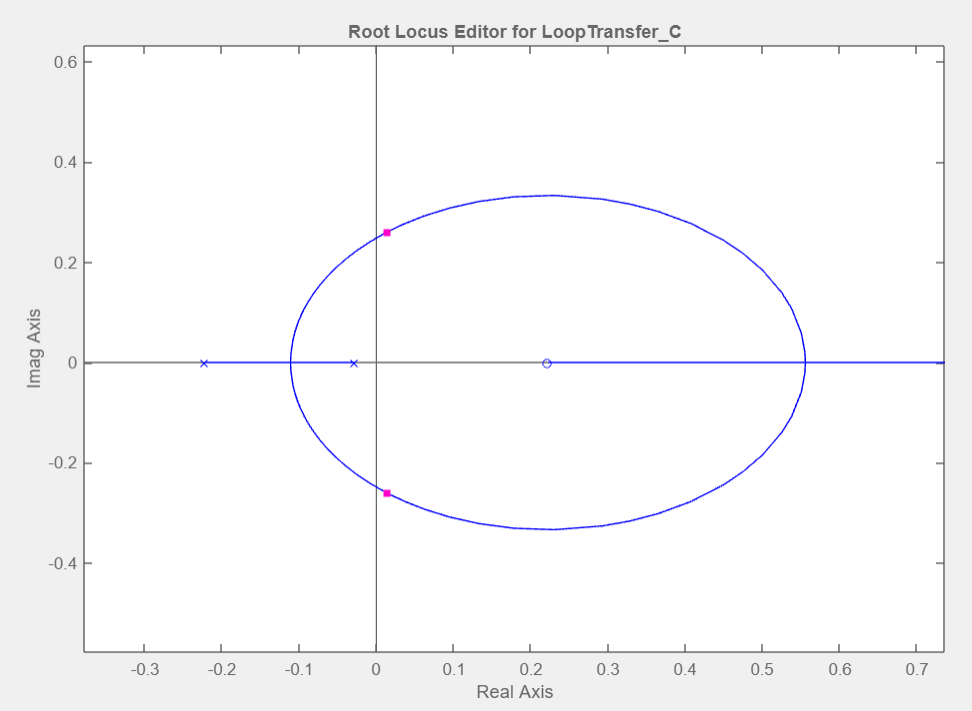

Com a adição do polo na origem, temos:

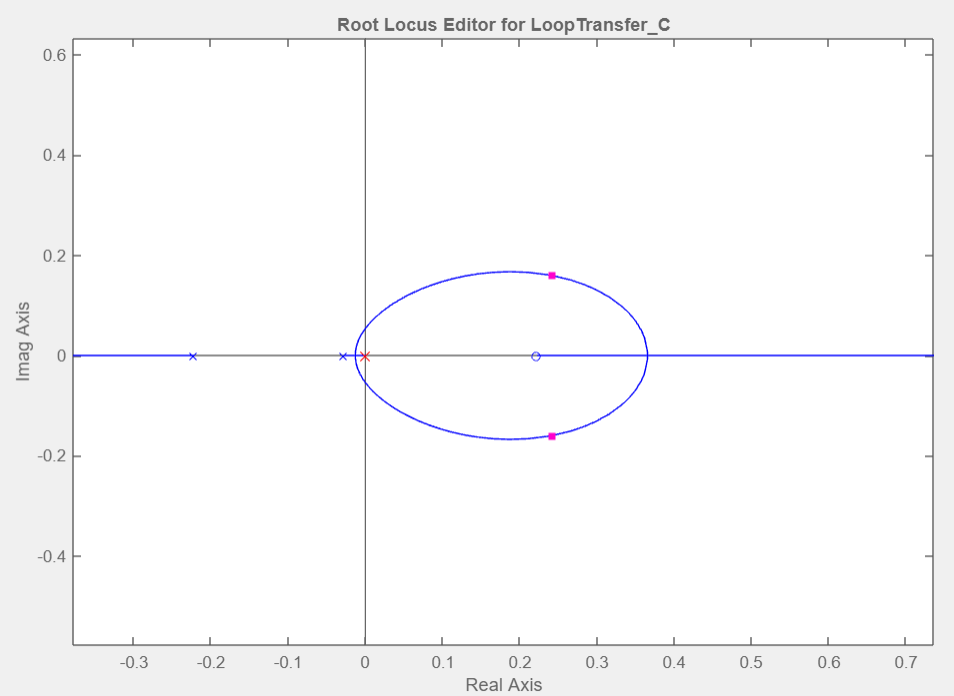

Observa-se que a adição do polo na origem reduziu os valores de Kp para os quais o sistema é estável (O LR está majoritariamente do lado direito). Sabemos que o formato do LR vai depender da localizacão do zero $s=-\frac{\textrm{Ki}}{\textrm{Kp}}$. Assim, com a adição do zero queremos trazer o LR mais para o lado esquerdo:

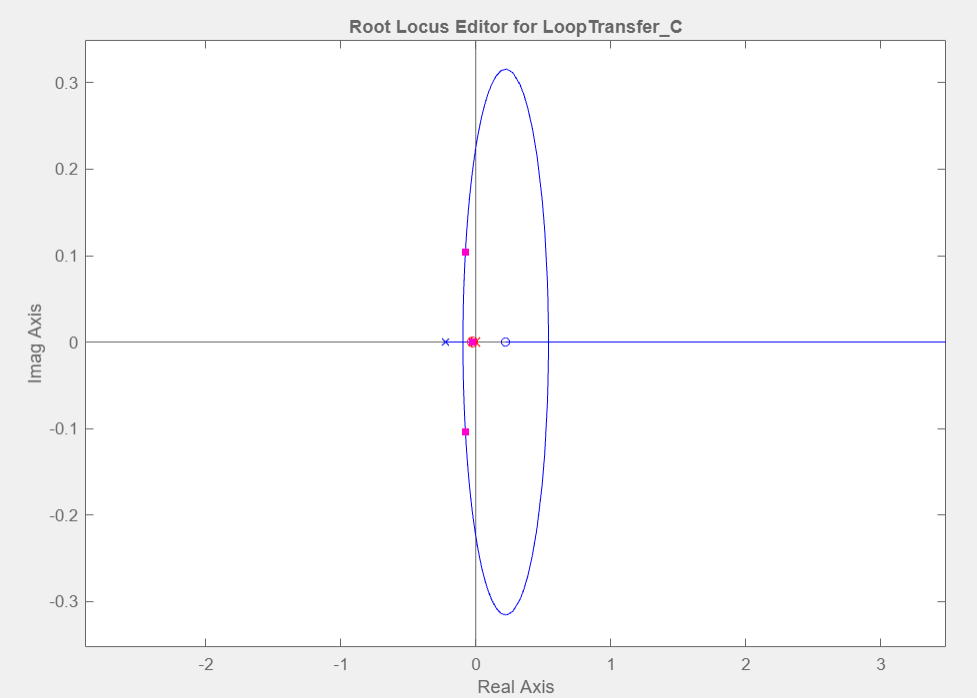

A melhor localização do zero para cumprir com esse objetivo foi em -0.025, entre os dois polos originais do sistema, mas especialmente próximo do mais dominante. As outras localizações experimentadas não conseguiram o mesmo efeito.

Após posicionar o zero da melhor forma, ajustamos Kp manualmente - isso é feito arrastando as bolinhas cor de rosa - para obter uma resposta estável e dentro da especificação do $IAE\leq iae_{G1}$. O valor obtido para Kp foi, portanto, de 0.26034.

Kp=0.26034;

E então podemos calcular Ki: 


$$s=-\frac{\textrm{Ki}}{\textrm{Kp}}$$



$$-0\ldotp 025=-\frac{\textrm{Ki}}{0\ldotp 26034}$$


Ki = $0\ldotp 0065085\;$

Portanto, o controlador C1 obtido é o seguinte:

C1=Kp*((s+0.025)/s)

C1 =
 
  0.2603 s + 0.006509
  -------------------
           s
 
Continuous-time transfer function.
Model Properties


Apresentação do resultado: simulação e o cálculo do IAE usando o controlador C1 projetado.

M1=feedback(C1*G1,1);
[y,t]=step(M1);
erro=1-y(end)

erro = 0.0046

O valor de erro=0.0046 é insignificante, assim, podemos dizer que a especificação de erro nulo foi atendida e isso foi graças ao polo na origem (integrador).

t=linspace(0,max(t),200);
y=step(M1,t);
plot(t,y);xlabel('Tempo(s)');
iae1=trapz(t,abs(1-y))

iae1 = 18.8283

O novo valor de IAE cumpre com a especificação, pois é menor que o IAE original (18.8283 < 20.1513).

A resposta para o projeto do PI para a FOPTD dada é ilustrada abaixo: 

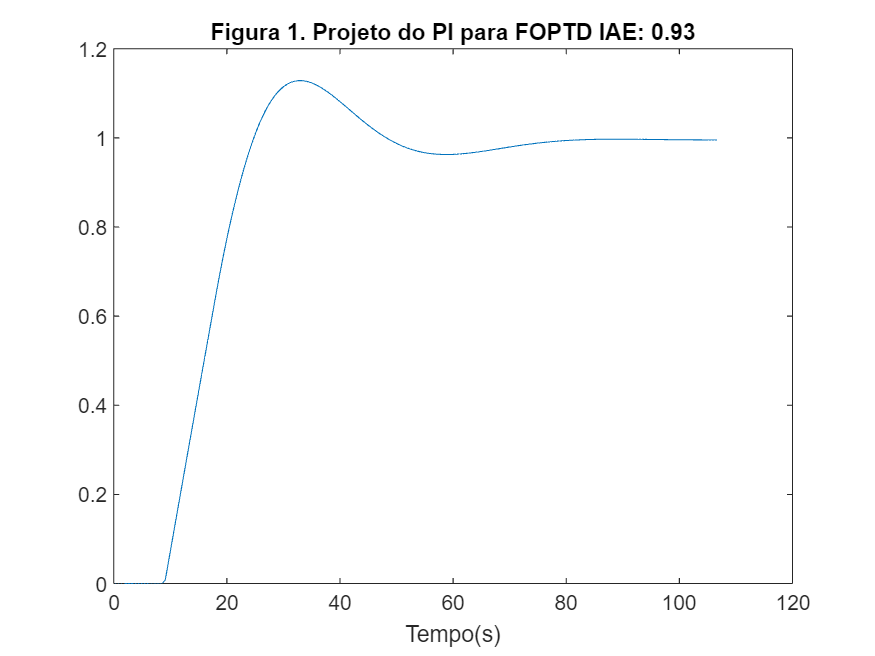

ss=sprintf('Figura 1. Projeto do PI para FOPTD IAE: %3.2f', iae1/iae_G1);
title(ss);

**Atividade 2: Projeto de um controlador C2  tipo PD via método do LR para o modelo de ordem 3 G2(s) que permita obter o  tempo de estabilização **$ts\leq ts_{G2}$** e com sobreelevação menor que 1%.**

Mostrar o controlador e o LR utilizado, explicar as escolhas da localização do zero do controlador para atender a especificação e a obtenção de Kp e Kd do LR.

G2

G2 =
 
           21
  --------------------
  s^3 + 58 s^2 + 792 s
 
Continuous-time transfer function.
Model Properties


polos_G2=pole(G2)

polos_G2 =      0
   -36
   -22


ts_G2

ts_G2 = 0.3241

Nossa G2 possui 3 polos no eixo real (em -36, -22 e na origem) e nenhum zero.

O controlador PD é dado por: 


$$\textrm{Gc}\left(s\right)=\textrm{Kp}+\textrm{Kds}$$


ou 


$$\textrm{Gc}\left(s\right)$$

$$=\textrm{Kd}\;\left(1+\frac{\textrm{Kp}}{\textrm{Kd}}s\right)$$


Tal que Kp deve ser escolhido para atender ao erro em regime e o tempo de estabelecimento enquanto Kd deve atender a condição de transitório, especificado em termos de sobreelevação.

O projeto do PD via LR também pode ser feito via 'rltool'. Adiciona-se o zero do PD $\left(s=-\frac{\textrm{Kp}}{\textrm{Kd}}\right)$ e ajusta-se o ganho Kd para a resposta desejada, enquanto Kp/Kd fica fixo.

%rltool(G2)

A seguir, o LR obtido para a G2 original, ao chamar 'rltool':

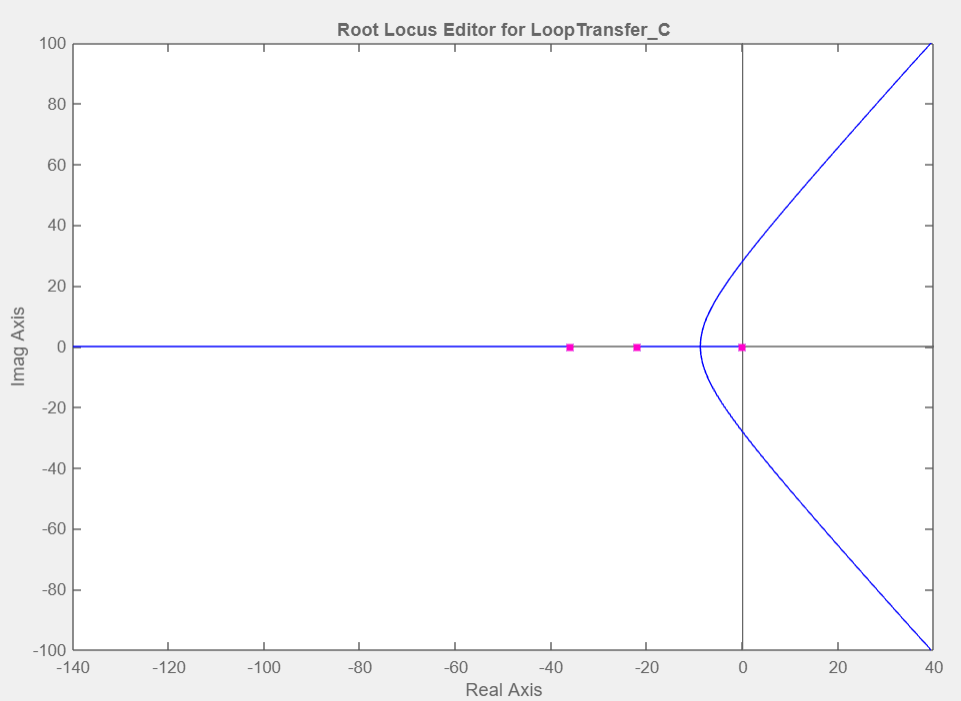

Para um zero muito afastado da origem, as respostas apresentavam muita oscilação ao se aumentar o ganho e não foi possível chegar ao tempo de estabelecimento especificado. O exemplo abaixo ilustra o LR e a resposta após a adição do zero em -80:

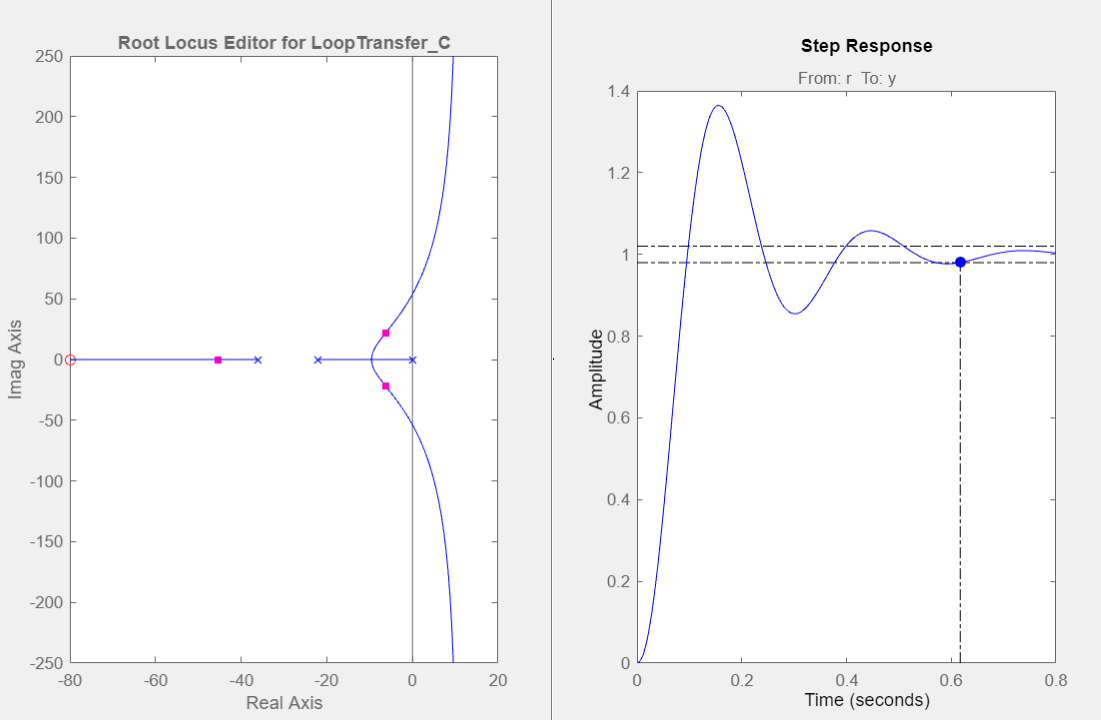

Enquanto que para um zero muito próximo da origem, o sistema tornou-se demasiado lento de forma que era preciso aumentar muito o ganho para se aproximar do tempo de estabelecimento pedido, mas esse aumento excessivo de ganho também resultava em oscilações que não permitiam que atingissemos o ts especificado. O exemplo abaixo ilustra o LR e a resposta após a adição do zero em -1:

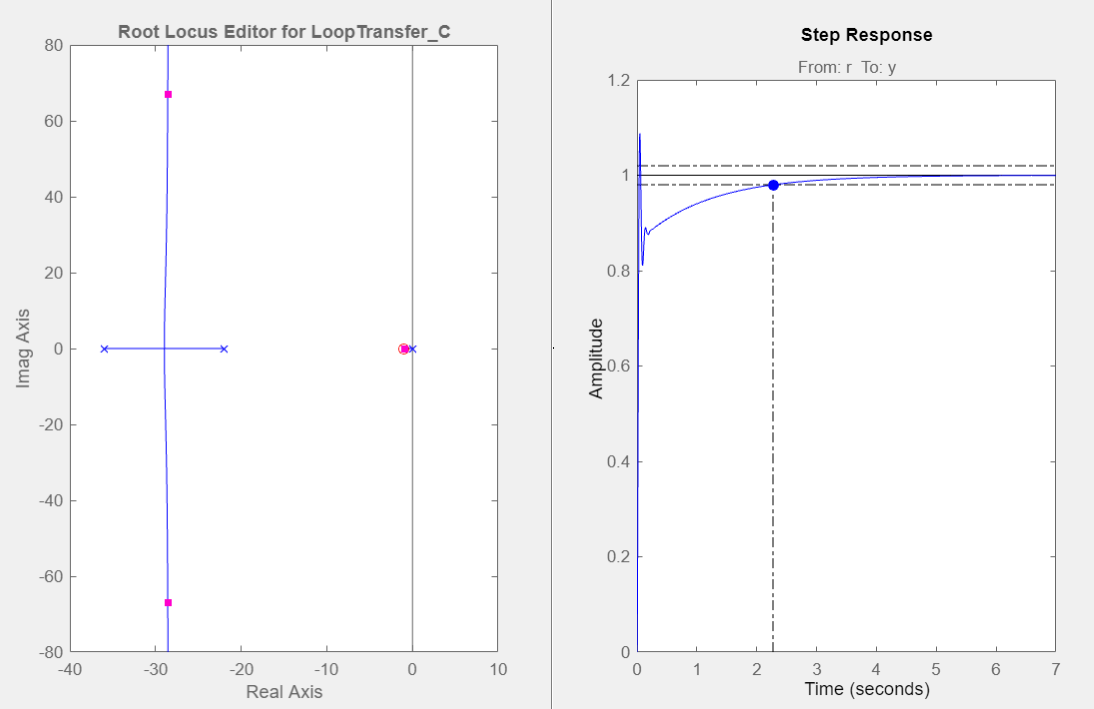

Dessa forma, uma boa localização para o zero, após os testes, foi encontrada em -24, entre os polos -22 e -36, já que localização do zero obteve um sistema estável para qualquer valor de K>0. O LR e a resposta são mostrados abaixo. Feito isso, fomos alterando manualmente o valor de Kd (movimentando a bolinha cor de rosa), até chegar em um valor que resultasse em uma resposta ao degrau que atendesse à especificação do tempo de estabelecimento, o que foi possível no valor de Kd=18.

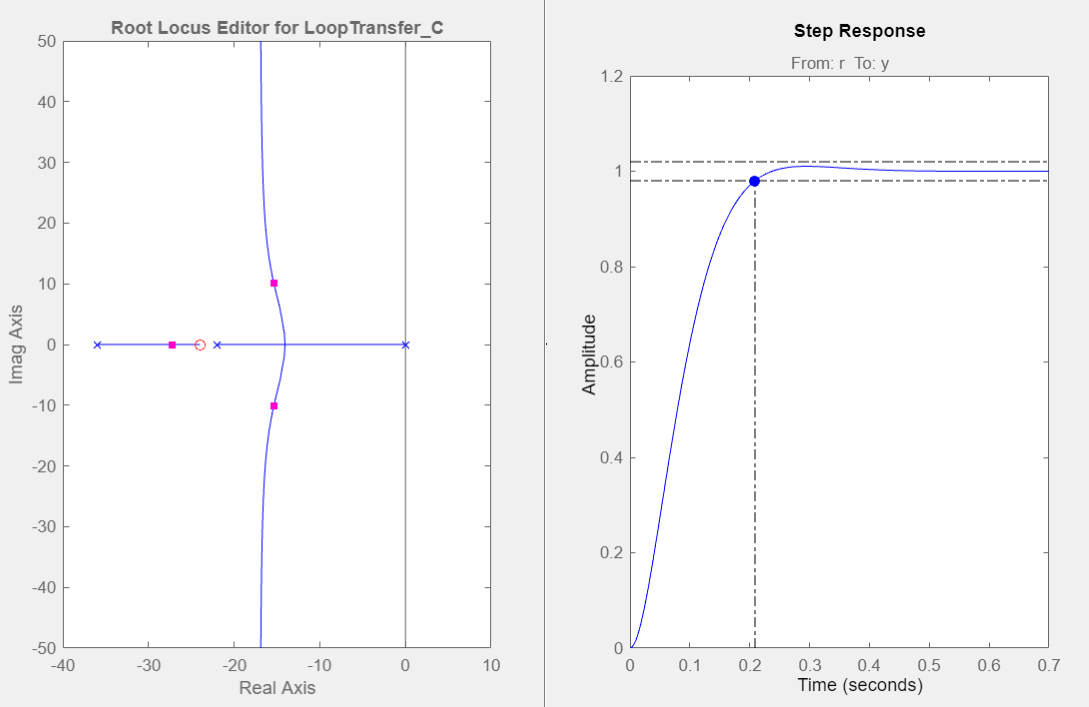

Kd=18;

Assim, podemos calcular o valor de Kp:


$$s=-\frac{\textrm{Kp}}{\textrm{Kd}}$$



$$-24=-\frac{\textrm{Kp}}{18}$$


Kp = 432

Portanto, o controlador C2 obtido é o seguinte:

C2=Kd*(s+24)

C2 =
 
  18 s + 432
 
Continuous-time transfer function.
Model Properties


Abaixo a simulação com o controlador C2 projetado.

M2=feedback(C2*G2,1);
[y,t]=step(M2);
ts2=stepinfo(M2).SettlingTime

ts2 = 0.2134

A especificação para o tempo de estabelecimento é atendida (0.2134 $\leq$ 0.3241).

UP2=stepinfo(M2).Overshoot

UP2 = 0.9339

O overshoot, ou máximo sobressinal, também foi atendido (0.9339% < 1%)

t=linspace(0,max(t),200);
y=step(M2,t);

A resposta para o projeto do PD para a FT de terceira ordem dada é ilustrada abaixo. Com a linha vertical destacando o antigo tempo de estabelecimento é notório que a resposta ficou mais rápida.

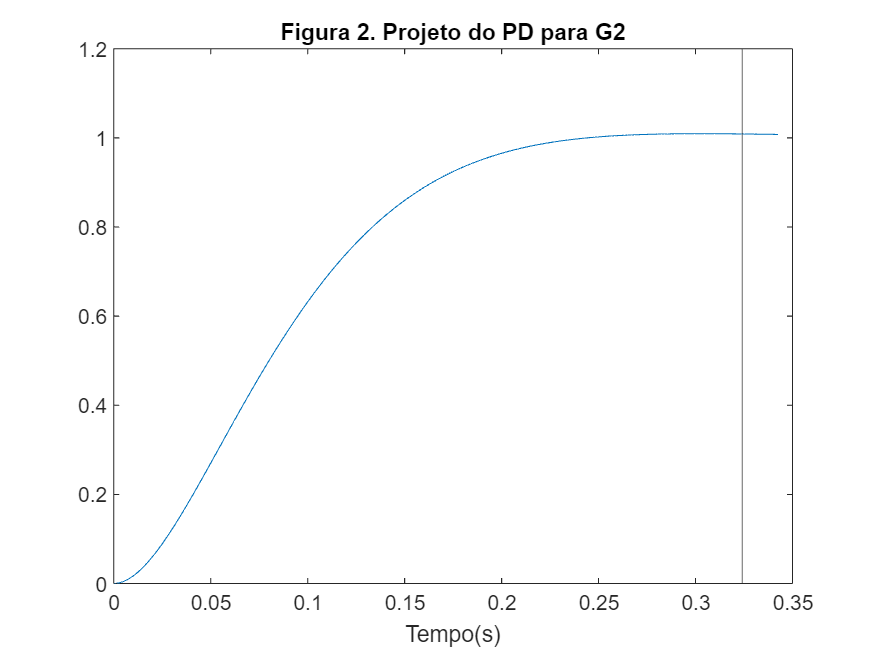

plot(t,y);xline(ts_G2);
xlabel('Tempo(s)');title('Figura 2. Projeto do PD para G2');

**Atividade 3: Projeto de um controlador C3 PI ou PID para o modelo de ordem 4 G3(s) tal que se tenha **$IAE\leq iae_{G3}$.

Mostrar o(s) LR utilizado(s), explicar as escolhas para obter o controlador e atender a especificação e a obtenção dos ganhos do PID no LR.

G3

G3 =
 
              2400
  -----------------------------
  s^4 + 4 s^3 + 6 s^2 + 4 s + 1
 
Continuous-time transfer function.
Model Properties


polos_G3=pole(G3)

polos_G3 =   -1.0002 + 0.0000i
  -1.0000 + 0.0002i
  -1.0000 - 0.0002i
  -0.9998 + 0.0000i


iae_G3

iae_G3 = 3.6378

O controlador escolhido para projeto foi o PID, que é dado por:


$$\textrm{Gc}\left(s\right)=\textrm{Kp}+\frac{\textrm{Ki}}{s}+\textrm{Kds}$$


O procedimento é projetar um controlador PI de forma a obter uma resposta rápida, mesmo que com sobreelevação e depois projetar então um controlador PD para melhorar a estabilidade relativa, reduzindo a sobreelevação.

%rltool(G3)

Chamando 'rltool', eis o LR obtido para a G3 dada:

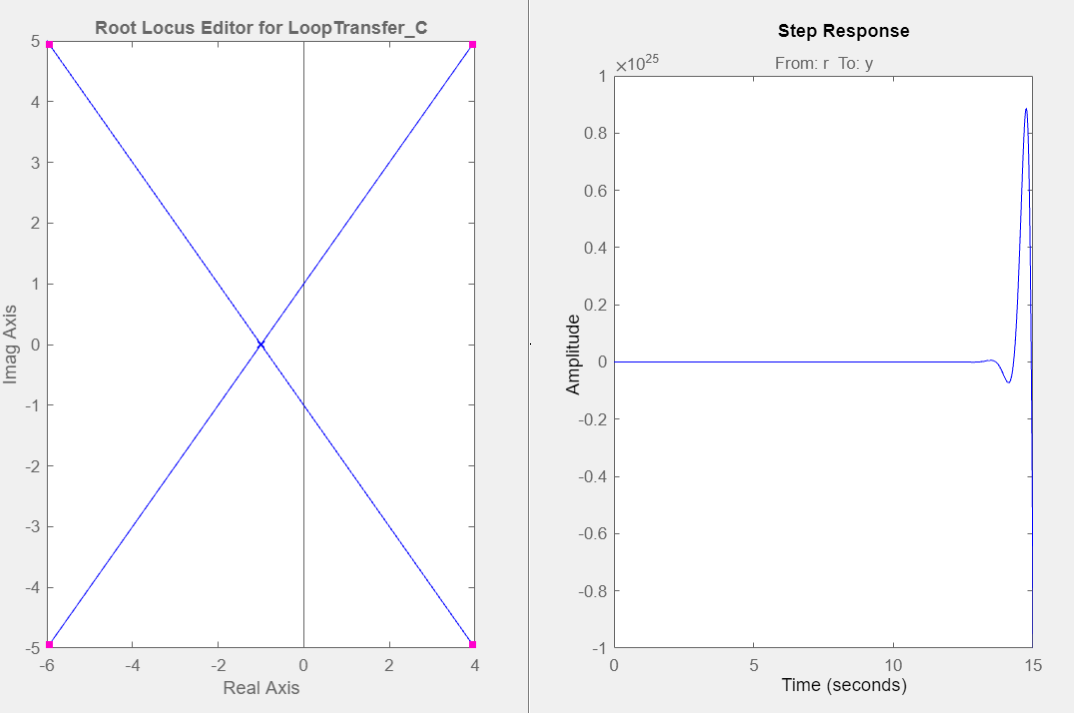

Como já descrito na primeira questão, o controlador PI adiciona um polo na origem e um zero que devemos escolher a localização, assim como também escolhemos o ganho Kp. Depois disto, calcula-se o ganho KI.

Com a adição do polo integrador (na origem), temos:

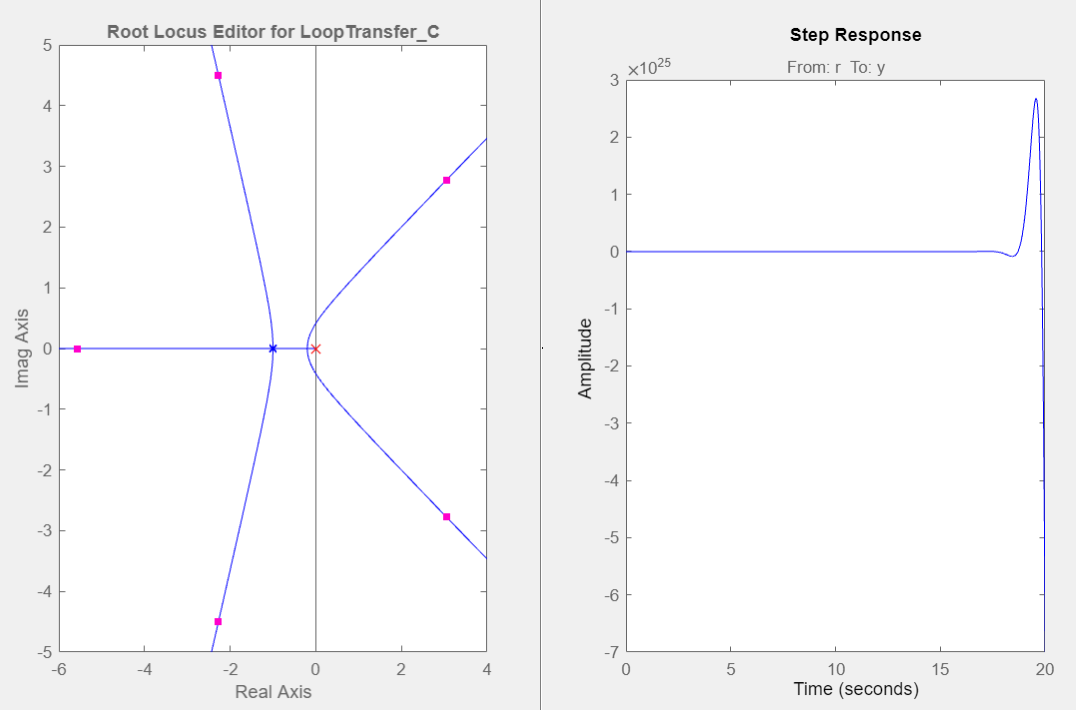

E após testes, uma boa localização encontrada para o zero foi em -0.5, sobre o eixo real, pois, dessa forma obtivemos uma resposta rápida, mesmo que com sobreelevação - o projeto do PD irá ajustar isso posteriormente. O ganho Kp também foi ajustado para isso e seu valor obtido foi de 0.00042499 - ilustrado abaixo. O LR e a resposta são os seguintes:

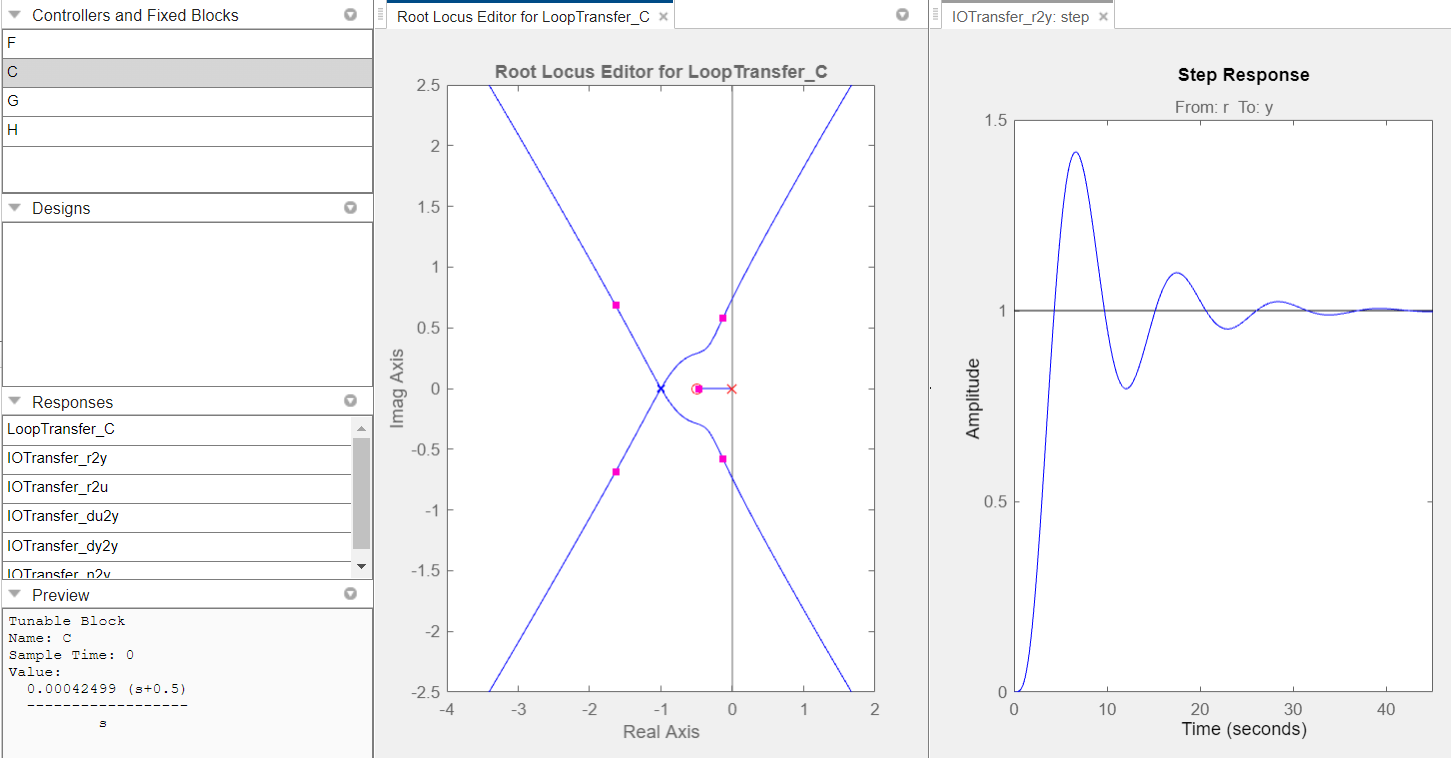

Importante destacar aqui que, assim como nas situações anteriores, essa localização do zero do PI e a escolha de Kp são um equilíbrio entre os efeitos de deixar o sistema rápido demais porém muito oscilante ou deixar o sistema pouco oscilante porém lento demais.

Para este Kp temos um Ki de:


$$s=-\frac{\textrm{Ki}}{\textrm{Kp}}$$



$$-0\ldotp 5=-\frac{\textrm{Ki}}{0\ldotp 00042499}$$


Ki = $0\ldotp 000212495$

Agora, o projeto do PD deve ajustar a questão da sobreelevação. Como já comentado na segunda questão, o PD adiciona mais um zero, cuja localização devemos ajustar, juntamente com o ganho Kd, que deve atender a condição de transitório, especificado em termos de sobreelevação.

Aproximar o zero do PD da origem aumenta o efeito derivativo, e permite assim aumentar o ganho proporcional, que torna a resposta mais rápida, além de melhorar nossa sobreelevação. Portanto, para conseguir o que queremos, precisamos do zero do PD relativamente próximo da origem.

Na imagem abaixo, uma boa localização para o zero do PD, após testes, foi em -0.62, sobre o eixo real, que, aliado ao Kd ajustado em 0.00068546, obteve uma resposta que continua sendo rápida, mas com uma melhor sobreelevação:

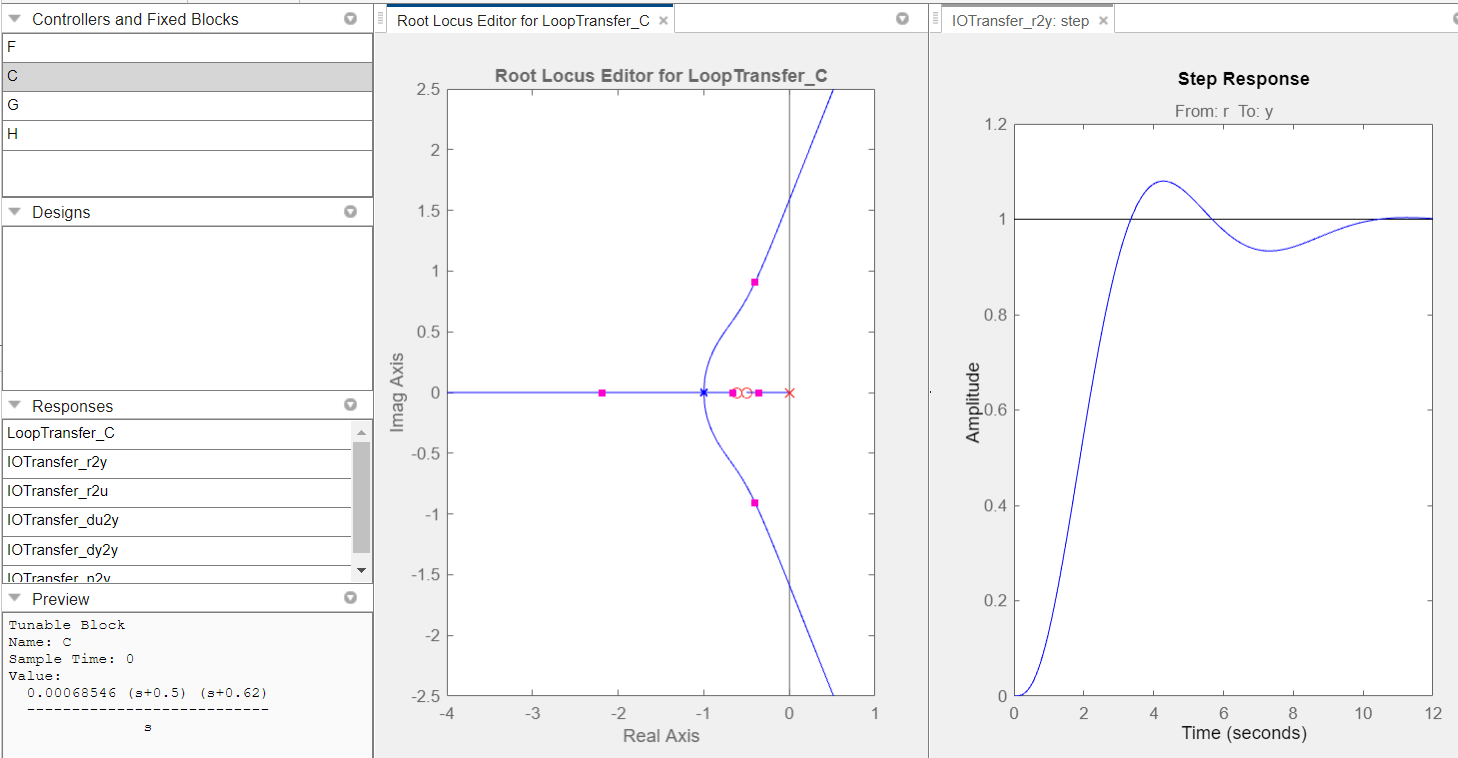

Sendo assim, o projeto do controlador já está exibido na imagem acima no canto esquerdo inferior e fica:

Kd=0.00068546;
C3=Kd*((s+0.5)*(s+0.62))/s

C3 =
 
  0.0006855 s^2 + 0.0007677 s + 0.0002125
  ---------------------------------------
                     s
 
Continuous-time transfer function.
Model Properties


Onde o polo na origem e o zero em -0.5 foram introduzidos no projeto do PI e o zero em -0.62 foi introduzido no projeto do PD. A união desses projetos configura nosso PID.

Os ganhos podem ser exibidos com o chamar da função 'pid':

pid(C3)

ans =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.000768, Ki = 0.000212, Kd = 0.000685
 
Continuous-time PID controller in parallel form.
Model Properties


Observe que, como prometido, o efeito derivativo aumentou o ganho proporcional inicialmente obtido com o PI, deixando a resposta mais rápida além de ter melhorado a sobreelevação.

Abaixo a simulação e o cálculo do IAE usando o controlador C3 projetado.

M3=feedback(C3*G3,1);
[y,t]=step(M3);
t=linspace(0,max(t),200);
y=step(M3,t);
plot(t,y);xlabel('Tempo(s)');
iae3=trapz(t,abs(1-y))

iae3 = 2.1908

A especificação para o IAE é atendida (2.1908 < 3.6378).

A resposta para o projeto do PID para a FT de quarta ordem dada é ilustrada abaixo.

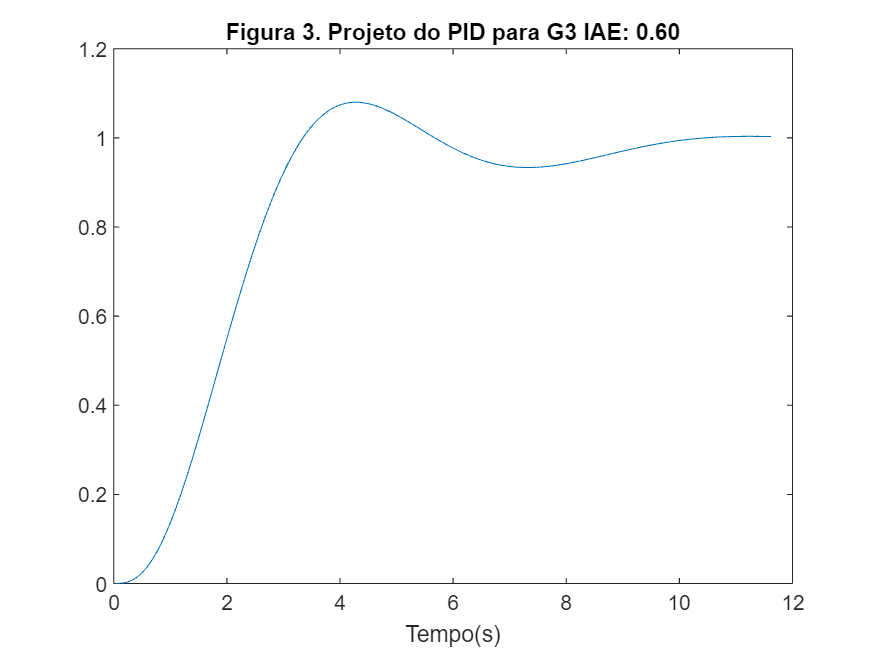

G =
 
  s^2 + 5 s + 6
  -------------
     s^2 + s
 
Continuous-time transfer function.
Model Properties


polos_G =      0
    -1


zeros_G =    -3.0000
   -2.0000


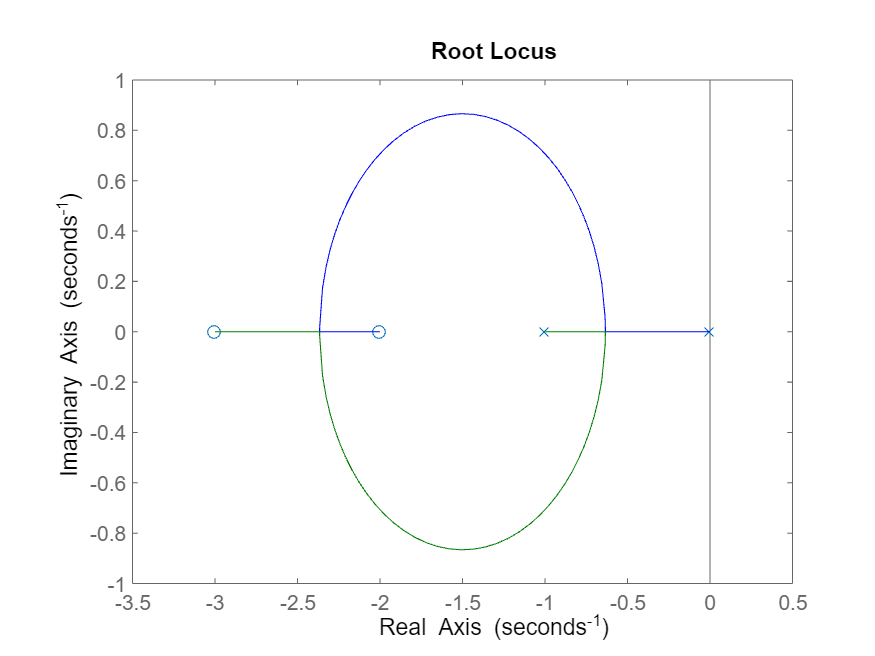

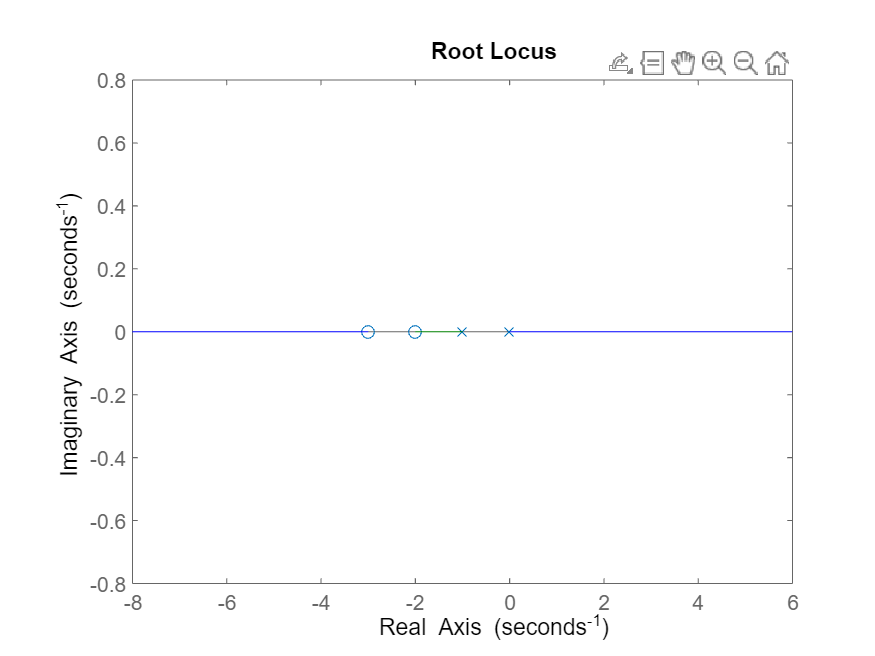

ss=sprintf('Figura 3. Projeto do PID para G3 IAE: %3.2f', iae3/iae_G3);
title(ss);